# Canonical Correlation Analysis

## Import data

inputFileStr='G:\My Drive\Nithin\Job Search\JEPostDoc\Data\2018ja025430-sup-0001-data_set_si-s01.txt';

Table = readtable(inputFileStr);
Table.Properties.VariableNames...
    ([5,6,7,8,9,10,11,12,13,14,15,16,17,18])...
    = {'S1','E1','E1_E1pred','Y1_AL','Y2_AU','Y3_PCI',...
    'Y4_Kp','Y5_am','Y6_Dst','Y7_mPe','Y8_mPi','Y9_Pips',...
    'Y10_Fe130','Y11_Ssince'};

time = datetime(Table.year,1,Table.day,Table.hr,0,0,0);

% G = [Table.Y1_AL,Table.Y2_AU,Table.Y3_PCI,Table.Y4_Kp,Table.Y6_Dst];
% G = [Table.Y1_AL,Table.Y2_AU,Table.Y4_Kp,Table.Y_13__log_vsw_,Table.Y_14__log_nsw_,Table.Y_15__sin2_theta_2_3,Table.Y_17__log_Bmag_];
G = [Table.Y1_AL,Table.Y2_AU,Table.Y4_Kp,Table.Y_13__log_vsw_,Table.Y_14__log_nsw_,Table.Y_17__log_Bmag_];
% G = [Table.Y1_AL,Table.Y2_AU,Table.Y3_PCI,Table.Y4_Kp,Table.Y5_am,Table.Y6_Dst,...
%     Table.Y9_Pips,Table.Y10_Fe130,Table.Y11_Ssince,Table.Y_12__abs_Tilt_,Table.Y_13__log_vsw_,...
%     Table.Y_14__log_nsw_,Table.Y_15__sin2_theta_2_3,Table.Y_16___Bz,Table.Y_17__log_Bmag_,Table.Y_18__thetaBn3,...
%     Table.Y_19__Rqint10];
P = [Table.Y7_mPe,Table.Y8_mPi];

[A,B,r,U,V,stats] = canoncorr(G,P);
[G1,G2,P1,P2] = composite_index(G,P,A,B);


## Get higher temporal resolution data

omnih5= 'G:\My Drive\Research\Projects\Data\omni.h5';
omni.time = h5read(omnih5,'/Time');
omni.time = unixtime2matlab(omni.time);
omni.AL = h5read(omnih5,'/Indices/AL');
omni.AU = h5read(omnih5,'/Indices/AU');
omni.Kp = h5read(omnih5,'/Indices/Kp');
omni.Vsw = h5read(omnih5,'/Velocity/V');
omni.nsw = h5read(omnih5,'/ProtonDensity');
omni.BxGSE = h5read(omnih5,'/BField/BxGSE');
    omni.ByGSE = h5read(omnih5,'/BField/ByGSE');
omni.BzGSE = h5read(omnih5,'/BField/BzGSE');
omni.Bmag = sqrt(omni.BxGSE.^2+omni.ByGSE.^2+omni.BzGSE.^2);

omni.AL(omni.AL==99999)=nan;
omni.AU(omni.AU==99999)=nan;
input.AL = normalize(log10(1+abs(omni.AL')));
input.AU = normalize(log10(1+abs(omni.AU')));
input.Kp = normalize(omni.Kp');
input.Vsw = normalize(log10(omni.Vsw'));
input.nsw = normalize(log10(omni.nsw'));
input.Bmag = normalize(log10(omni.Bmag'));

index = ~isnan(input.AL) & ~isnan(input.AU) & ~isnan(input.Kp) &  ~isnan(input.Vsw) & ~isnan(input.nsw) & ~isnan(input.Bmag);

G_new = [input.AL(index), input.AU(index), input.Kp(index), input.Vsw(index), input.nsw(index), input.Bmag(index)];

G_i = G_new*A;

time_i = omni.time(index);

## Plotting the composite indices

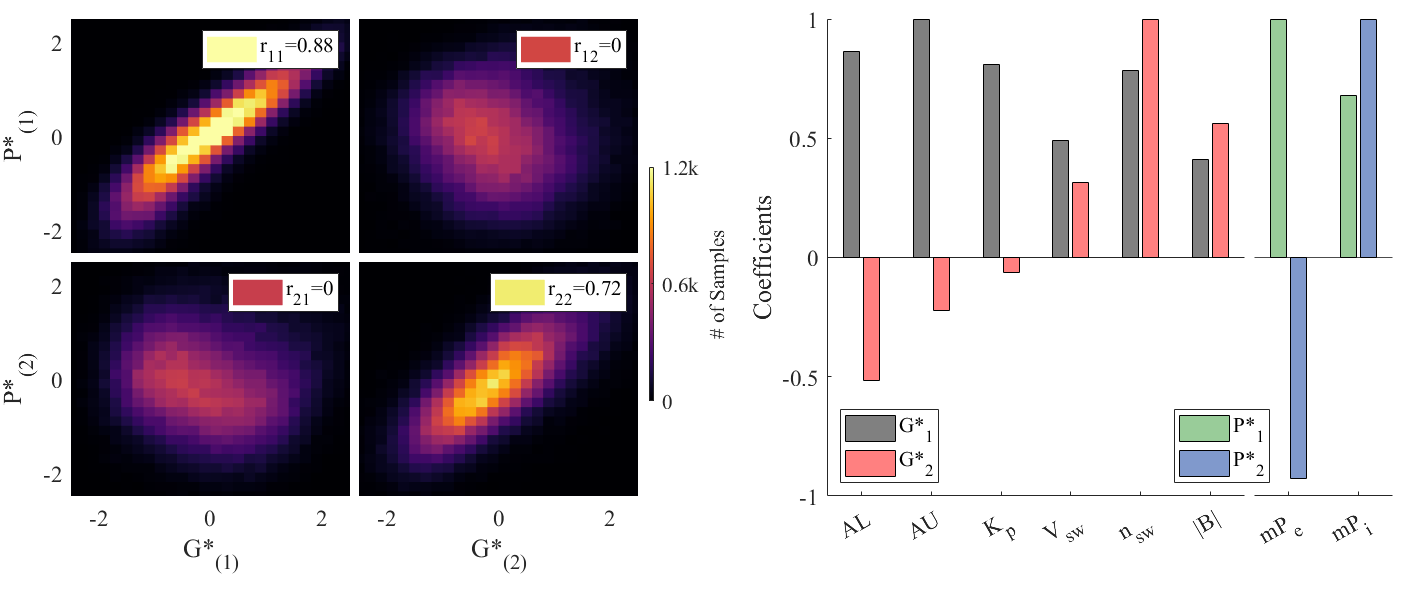

figureHandle=figure;
resize_figure(figureHandle,125,300);
colormap('inferno');

p = panel();
p.pack(1,2);
p.margintop = 4;
% p.marginleft = 15;
p.marginbottom = 20;
p.fontsize=14;
p.fontname='Times';
p(1,1).pack(2,2);
p(1,2).pack('h',{3/4 []});
p.select('all');
p(1,1).de.margin=2;
p(1,1).marginright = 40;
% p.de.marginright=30;

p(1,1,1,1).select();
histogram2(G1,P1,'DisplayStyle','tile','ShowEmptyBins','on','EdgeColor','none'); 
% c11=colorbar_thin('YLabel','# of Samples');
xlim([-2.5,2.5]);
ylim([-2.5,2.5]);
% xlabel('G1');
ylabel('P*_{(1)}');
set(gca,'XTickLabel','','YTick',[-2,0,2]);
caxis([0,1200]);
R11=corrcoef(G1,P1);
legend(['r_1_1=',num2str(R11(1,2),2)]);

p(1,1,1,2).select();
histogram2(G2,P1,'DisplayStyle','tile','ShowEmptyBins','on','EdgeColor','none');
c12=colorbar_thin('YLabel','# of Samples');
set(c12,'Position',get(c12,'Position')-[0,0.25,0,0],'Units','normalized');
c12.Ticks=[0,600,1200]; c12.TickLabels={'0','0.6k','1.2k'};

xlim([-2.5,2.5]);
ylim([-2.5,2.5]);
% xlabel('G2');
% ylabel('P1');
set(gca,'YTickLabel','','XTickLabel','');
caxis([0,1200]);
R12=corrcoef(G2,P1);
legend(['r_1_2=',num2str(round(R12(1,2),2),2)]);

p(1,1,2,1).select();
histogram2(G1,P2,'DisplayStyle','tile','ShowEmptyBins','on','EdgeColor','none'); 
% c11=colorbar_thin('YLabel','# of Samples');
xlim([-2.5,2.5]);
ylim([-2.5,2.5]);
set(gca,'YTick',[-2,0,2],'XTick',[-2,0,2]);
xlabel('G*_{(1)}');
ylabel('P*_{(2)}');
caxis([0,1200]);
R21=corrcoef(G1,P2);
legend(['r_2_1=',num2str(round(R21(1,2),2),2)]);


p(1,1,2,2).select();
histogram2(G2,P2,'DisplayStyle','tile','ShowEmptyBins','on','EdgeColor','none'); 
% c11=colorbar_thin('YLabel','# of Samples');
xlim([-2.5,2.5]);
ylim([-2.5,2.5]);
xlabel('G*_{(2)}');
% ylabel('P2');
set(gca,'YTickLabel','','XTick',[-2,0,2]);
caxis([0,1200]);
R22=corrcoef(G2,P2);
legend(['r_2_2=',num2str(R22(1,2),2)]);

% figureHandle2=figure;
% resize_figure(figureHandle2,125,150);
% p = panel();

% p.select('all');
p(1,2).de.margin = 2;
p(1,2,1).select();
% cx={'AL','AU','PCI','K_p','Dst','Am'};
% cx={'AL','AU','PCI','K_p','Am','Dst','P_{ips}','F_{e130}','S_{since}','Tilt','V_{sw}','n_{sw}','sin^2(\theta)^(2/3)','B_z','|B|','\theta_{B_n^3}','R_{qint10}'};
cx = {'AL','AU','K_p','V_{sw}','n_{sw}','|B|'}; %'sin^2(\theta)^{2/3}'
x = categorical(cx);
x = reordercats(x,cx);
y = A(:,1);
ylim([-1,1]);
b1=bar(x,A./max(abs(A)));
b1(1).FaceColor = [0.5,0.5,0.5];
b1(2).FaceColor = [1,0.5,0.5];
ylabel('Coefficients');
l1=legend('G*_1','G*_2','Location','southwest');
set(gca,'YTick',[-1,-0.5,0,0.5,1]);

p(1,2,2).select();
% cx={'AL','AU','PCI','K_p','Dst','Am'};
dx={'mP_{e}','mP_{i}'};
x = categorical(dx);
x = reordercats(x,dx);
b2=bar(x,B./max(abs(B)),0.8);
b2(1).FaceColor = [0.6,0.8,0.6];
b2(2).FaceColor = [0.5,0.6,0.8];
% ylabel('Coefficients');
ylim([-1,1]);
set(gca,'YTickLabel','','YColor','none','YTick',[-1,-0.5,0,0.5,1]);
hold on;
% plot(get(gca,'xlim'),[0 0],'k');
yline(0,'-k');
l2=legend([b2(1) b2(2)],'P*_1','P*_2','Location','southwestoutside');
l2.Position(2) = l1.Position(2);
l2.Position(1) = l2.Position(1) -0.05;
export_fig('G:\My Drive\Nithin\Job Search\JEPostDoc\Data\Final\Fig4_corr_and_coeff.pdf','-r600','-pdf','-nocrop');

## Deriving m_pe and m_pi

g1 = polyfit(G1,P1,1);
g2 = polyfit(G2,P2,1);
P_i = [G_i(:,1).*g1(1)+g1(2), G_i(:,2).*g2(1)+g2(2)];
mP = (P_i*inv(B));

## Plotting cca examples

lw=1.5;
figureHandle2 = figure;
resize_figure(figureHandle2,100,300);
p=panel();
p.pack({{70}},{{75} {78} {78}});
p.margintop=15;
p.marginleft=18;
p(1,2).pack(3,1);
p(1,2).marginleft=10;
p(1,3).marginleft=15;

p(1,3).pack(3,1);
p.fontsize=14;
p.fontname='Times';
p.select('all');

**Panel 1**


p(1,1).select();
colormap(inferno);
p(1,1).marginright=30;
p(1,2).de.margin = 4;

histogram2(G_i(:,1),G_i(:,2),'DisplayStyle','tile','ShowEmptyBins','on','EdgeColor','none'); 
c11=colorbar_thin('YLabel','# of Samples');
set(gca,'XTick',[-2.5,0,2.5],'YTick',[-2.5,0,2.5]);
xlim([-2.5,2.5]);
ylim([-2.5,2.5]);
x1h = xlabel('G*_{(1)}');
x1h.Position(2) = x1h.Position(2)+0.1;
y1h=ylabel('G*_{(2)}');
y1h.Position(1) = y1h.Position(1)+0.2;
c11.Ticks=[0,2000,4000]; c11.TickLabels={'0','2k','4k'};
hold on;
trange=535:1050;
trangeblue=530:550;
trangecyan=670:699;
trangegreen=1020:1050;
plot(G_i(trangeblue,1),G_i(trangeblue,2),'blue','LineWidth',lw);
text(G_i(trangeblue(1),1),G_i(trangeblue(1),2),['     ',datestr(omni.time(trangeblue(1)),'HH:MM')],'color','blue','FontSize',12,'FontName','Times');
hold on;
plot(G_i(trangegreen,1),G_i(trangegreen,2),'green','LineWidth',lw);
text(G_i(trangegreen(1),1),G_i(trangegreen(1),2),['      ',datestr(omni.time(trangegreen(1)),'HH:MM')],'color','g','FontSize',12,'FontName','Times');
hold on;
plot(G_i(trangecyan,1),G_i(trangecyan,2),'c','LineWidth',lw);
text(G_i(trangecyan(1),1),G_i(trangecyan(1),2),[datestr(omni.time(trangecyan(1)),'HH:MM'),'     '],'color','c','HorizontalAlignment','right','FontSize',12,'FontName','Times');
text(G_i(trangecyan(end),1),G_i(trangecyan(end),2),[datestr(omni.time(trangecyan(end)),'HH:MM'),'         '],'color','c','HorizontalAlignment','right','FontSize',12,'FontName','Times');

text(0.5,1.13,'A) Composite-index Space','Units','normalized','FontSize',18,'FontName','Times','horizontalAlignment','center');

**Panel 2**

p(1,2,1,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.AL(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.AL(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.AL(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.AL(trangegreen),'g','LineWidth',lw);

set(gca,'XTickLabel','');
text(0.8,0.3,'AL','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[nT]','Units','normalized','FontSize',12,'FontName','Times');
text(0.5,1.4,'B) Geomagnetic Indices','Units','normalized','FontSize',18,'FontName','Times','horizontalAlignment','center');

p(1,2,2,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.AU(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.AU(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.AU(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.AU(trangegreen),'g','LineWidth',lw);
set(gca,'XTickLabel','')
ylim([-100 100]);
text(0.8,0.3,'AU','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[nT]','Units','normalized','FontSize',12,'FontName','Times');

p(1,3).de.margin = 4;
p(1,2,3,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Kp(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Kp(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Kp(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Kp(trangegreen),'g','LineWidth',lw);
set(gca,'YTick',[4,6,8,10,12],'YTickLabel',{'4','','8','','12'});
text(0.8,0.3,'Kp','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[a.u]','Units','normalized','FontSize',12,'FontName','Times');

% p(1,2,4,1).select();
% plot(datetime(omni.time(trange),'ConvertFrom','datenum'),mP(trange,1),'r','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),mP(trangeblue,1),'b','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),mP(trangecyan,1),'c','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),mP(trangegreen,1),'g','LineWidth',lw);
% % set(gca,'XTickLabel','','YTick',[4,6,8,10,12],'YTickLabel',{'4','','8','','12'});
% text(0.8,0.4,'mP_e','Units','normalized','FontSize',18,'FontName','Times');
 

**Panel 3**

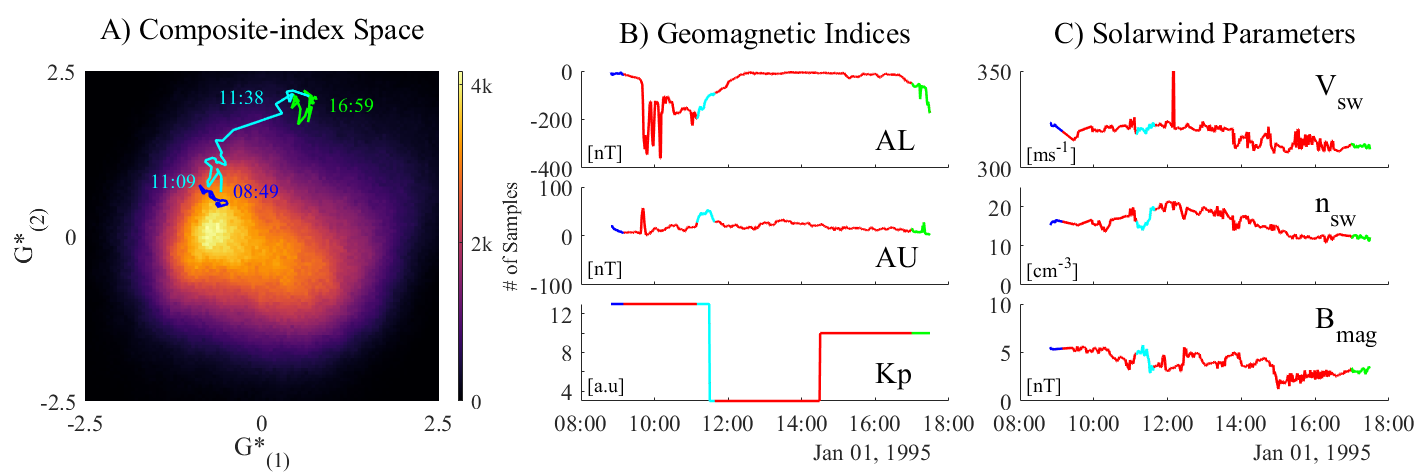

% Third panel
p(1,3,1,1).select();
omni.Vsw=interp_nans(omni.Vsw')';
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Vsw(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Vsw(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Vsw(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Vsw(trangegreen),'g','LineWidth',lw);
set(gca,'XTickLabel','');
ylim([300,350]);
text(0.8,0.8,'V_{sw}','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[ms^{-1}]','Units','normalized','FontSize',12,'FontName','Times');
text(0.5,1.4,'C) Solarwind Parameters','Units','normalized','FontSize',18,'FontName','Times','horizontalAlignment','center');

p(1,3,2,1).select();
omni.nsw=interp_nans(omni.nsw')';
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.nsw(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.nsw(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.nsw(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.nsw(trangegreen),'g','LineWidth',lw);
set(gca,'XTickLabel','');
ylim([0 25]);
text(0.8,0.8,'n_{sw}','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[cm^-^3]','Units','normalized','FontSize',12,'FontName','Times');

p(1,3,3,1).select();
omni.Bmag=interp_nans(omni.Bmag')';
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Bmag(trange),'r','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Bmag(trangeblue),'b','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Bmag(trangecyan),'c','LineWidth',lw);
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Bmag(trangegreen),'g','LineWidth',lw);
% set(gca,'XTickLabel','');
ylim([0 10]);
text(0.8,0.8,'B_{mag}','Units','normalized','FontSize',18,'FontName','Times');
text(0.015,0.18,'[nT]','Units','normalized','FontSize',12,'FontName','Times');

export_fig('G:\My Drive\Nithin\Job Search\JEPostDoc\Data\Final\Fig1_cca.pdf','-r600','-pdf','-nocrop');


% p(1,3,4,1).select();
% plot(datetime(omni.time(trange),'ConvertFrom','datenum'),mP(trange,2),'r','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),mP(trangeblue,2),'b','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),mP(trangecyan,2),'c','LineWidth',lw);
% hold on;
% plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),mP(trangegreen,2),'g','LineWidth',lw);
% % set(gca,'XTickLabel','','YTick',[4,6,8,10,12],'YTickLabel',{'4','','8','','12'});
% text(0.8,0.4,'mP_i','Units','normalized','FontSize',18,'FontName','Times');


figureHandle = figure;
resize_figure(figureHandle,120,300);
p=panel();
p.pack({{100}},{{100} {140}});
p(1,2).pack(6,1);
p.select('all');
p(1,2).de.margin=4;

p(1,1).select();
p(1,1).marginright=35;
colormap(inferno);
histogram2(G_i(:,1),G_i(:,2),'DisplayStyle','tile','ShowEmptyBins','on'); 
c11=colorbar_thin('YLabel','Samples');

xlim([-3,3]);
ylim([-3,3]);
xlabel('G1');
ylabel('G2');
% caxis([0,1200]);
hold on;

% plot(G_i(550:890,1),G_i(550:890,2),'.-w');
% hold on;
trange=535:1050;
trangeblue=530:550;
trangecyan=670:699;
trangegreen=1020:1050;

plot(G_i(trangeblue,1),G_i(trangeblue,2),'blue');
text(G_i(trangeblue(1),1),G_i(trangeblue(1),2),['     ',datestr(omni.time(trangeblue(1)),'HH:MM')],'color','blue');
hold on;
plot(G_i(trangegreen,1),G_i(trangegreen,2),'green');
text(G_i(trangegreen(1),1),G_i(trangegreen(1),2),['      ',datestr(omni.time(trangegreen(1)),'HH:MM')],'color','g');
hold on;
plot(G_i(trangecyan,1),G_i(trangecyan,2),'c');
text(G_i(trangecyan(1),1),G_i(trangecyan(1),2),[datestr(omni.time(trangecyan(1)),'HH:MM'),'     '],'color','c','HorizontalAlignment','right');
text(G_i(trangecyan(end),1),G_i(trangecyan(end),2),[datestr(omni.time(trangecyan(end)),'HH:MM'),'         '],'color','c','HorizontalAlignment','right');



p(1,2,1,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.AL(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.AL(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.AL(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.AL(trangegreen),'g');

set(gca,'XTickLabel','');
ylabel('AL');

p(1,2,2,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.AU(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.AU(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.AU(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.AU(trangegreen),'g');
set(gca,'XTickLabel','')
ylabel('AU');

p(1,2,3,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Kp(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Kp(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Kp(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Kp(trangegreen),'g');
set(gca,'XTickLabel','');
ylabel('Kp');

p(1,2,4,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Vsw(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Vsw(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Vsw(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Vsw(trangegreen),'g');
set(gca,'XTickLabel','');
ylabel('V_{sw}');

p(1,2,5,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.nsw(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.nsw(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.nsw(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.nsw(trangegreen),'g');
set(gca,'XTickLabel','');
ylabel('n_{sw}');

p(1,2,6,1).select();
plot(datetime(omni.time(trange),'ConvertFrom','datenum'),omni.Bmag(trange),'r');
hold on;
plot(datetime(omni.time(trangeblue),'ConvertFrom','datenum'),omni.Bmag(trangeblue),'b');
hold on;
plot(datetime(omni.time(trangecyan),'ConvertFrom','datenum'),omni.Bmag(trangecyan),'c');
hold on;
plot(datetime(omni.time(trangegreen),'ConvertFrom','datenum'),omni.Bmag(trangegreen),'g');
ylabel('B_{mag}');



figure;
plot(datetime(omni.time(535:1050),'ConvertFrom','datenum'),omni.AL(535:1050));


function [G1,G2,P1,P2] = composite_index(G,P,A,B)
    Temp1 = G*A;
    Temp2 = P*B;
    G1 = Temp1(:,1);
    G2 = Temp1(:,2);
    P1 = Temp2(:,1);
    P2 = Temp2(:,2);
end

function y = normalize(x)
    y = (x-nanmean(x))./nanstd(x);
end